# Predicting The Price Of Crytocurrency

Create a predictive model to forecast the price of Crytocurrency based on multiple technical indicators.  First starting with a smaller dataset to narrow down the choice of models, then once a model is selected scale up to train against larger datasets.

clear
clc
warning off

## Load In Data 

% Can select other coin name such as: ETH, LTC ... which has couple with
% USD to get data from Coinbase. It will get data from 01-Jan-2018 until now
coinName = "BTC";
file_name = strcat(coinName,".xlsx");
%Checking if data is not exist then will get data
if ~isfile(file_name)
  get_data(coinName);
end
priceData = table2timetable(readtable(file_name));
priceData = sortrows(priceData,'Time','ascend');
%Resample or aggregate data in timetable, and resolve duplicate or irregular times
resampleData=retime(priceData,'hourly','spline');

## Build Table Of Predictors

Specify the reponse variable to predict:

coinToPredict = resampleData.Close;

Create technical indicators derived from price data.

% extract all the coin names stored in priceData's metadata
data = resampleData.Properties.VariableNames;

for i = 1:length(data)
    price = resampleData(:,i);
    
    % calculate the moving average for various window sizes for Close data
    ma7 = movavg(price, 'linear', 7);
    ma25 = movavg(price, 'linear', 25);
    ma90 = movavg(price, 'linear', 90);
    
    %  calculates the Relative Strength Index (RSI) from the series of closing stock price for various window sizes
    rsi7 = rsindex(resampleData(:,"Close"), 'WindowSize', 7);
    rsi25 = rsindex(resampleData(:,"Close"), 'WindowSize', 25);
    rs90 = rsindex(resampleData(:,"Close"), 'WindowSize', 90);
    
    % calculates the typical prices (TP) from the series of high, low, and closing prices.
    % The typical price is the average of the high, low, and closing prices for each period.
     TP = typprice(resampleData);
     
    % easy to combine returns with other signals even with different sizes
    coinPredictors = synchronize(ma7, ma25, ma90, rsi7, rsi25, rs90, TP);
    
    % adjust column names & combine with other coin predictors
    columnNames = ["MA7" "MA25" "MA90" "RSI7" "RSI25" "RSI90" "TP"];
    coinPredictors.Properties.VariableNames = cellstr(data(i) + "_" + columnNames);
    
    % append each coin's predictors to entire data set used to trade
    if i > 1
        tradingData = synchronize(tradingData, coinPredictors);
    else
       tradingData = coinPredictors;
    end
end

% combine predictors and response together
tradingData.CoinPrice = coinToPredict

tradingData = 26761×36 timetable
            Time            Low_MA7    Low_MA25    Low_MA90    Low_RSI7    Low_RSI25    Low_RSI90    Low_TP    High_MA7    High_MA25    High_MA90    High_RSI7    High_RSI25    High_RSI90    High_TP    Open_MA7    Open_MA25    Open_MA90    Open_RSI7    Open_RSI25    Open_RSI90    Open_TP    Close_MA7    Close_MA25    Close_MA90    Close_RSI7    Close_RSI25    Close_RSI90    Close_TP    Volume_MA7    Volume_MA25    Volume_MA90

tradingData=fillmissing(tradingData,'spline');

## Create Testing & Training Data Sets

Break the data into a training dataset for model building, and a testing dataset to assess model performance. 

inSample = timerange('2018-01-01', '2021-01-01');
trainingData = timetable2table(tradingData(inSample,:));

outSample = timerange('2021-01-01', '2021-02-28');
testingData = timetable2table(tradingData(outSample,:));

## Use The Regression Learner App With Training Data Set

You can use Statistice & Machine Learning Toolbox for this app and select suite table training algorithm for best model

## 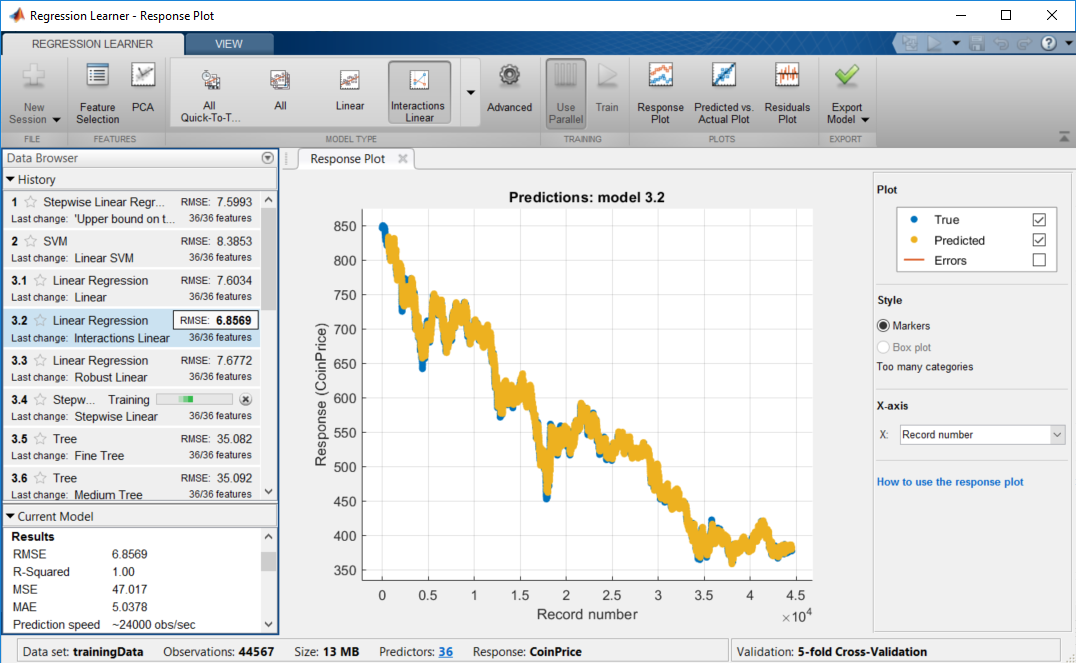

regressionLearner

## Predict Using The Testing Data Set

Use the trained model to predict with out-of-sample data using a single command.

predictedPrice = trainedModel.predictFcn(testingData);
RMSE = sqrt(mean((testingData.CoinPrice - predictedPrice).^2))

RMSE = 38.7208

## Compare Historical and Predicted Results

Compare the out-of-sample prediction with historical prices and visualize the results.

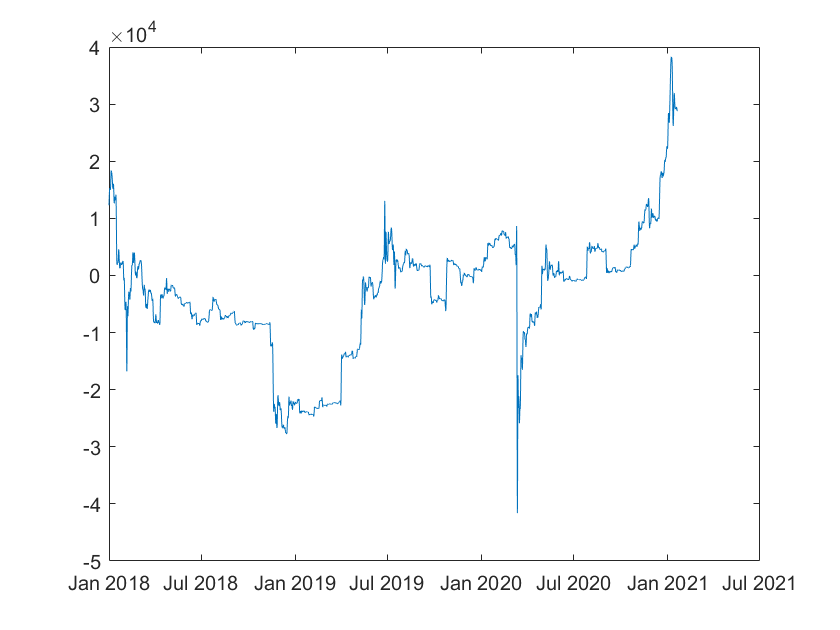

Date = testingData.Time;
historicalPrice = testingData.CoinPrice;

%calculates the Price and Volume Trend (PVT) from the series of closing stock prices and trade volume.
PVT = retime(pvtrend(priceData),'hourly','spline');
%Plot PVT
plot(PVT.Time,PVT.PriceVolumeTrend)

    
% create a table and visualize the comparison
resultsTable = timetable(Date, historicalPrice, predictedPrice)

resultsTable = 457×2 timetable
            Date            historicalPrice    predictedPrice
    ____________________    _______________    ______________

    01-Jan-2021 00:00:00         29413             29410     
    01-Jan-2021 01:00:00         29495             29492     
    01-Jan-2021 02:00:00         29585             29580     
    01-Jan-2021 03:00:00         29681             29676     
    01-Jan-2021 04:00:00         29783             29778     
    01-Jan-2021 05:00:00         29890             29886     
    01-Jan-2021 06:00:00         30002             29999     
    01-Jan-2021 07:00:00         30119             30117     
    01-Jan-2021 08:00:00         30239             30238     
    01-Jan-2021 09:00:0

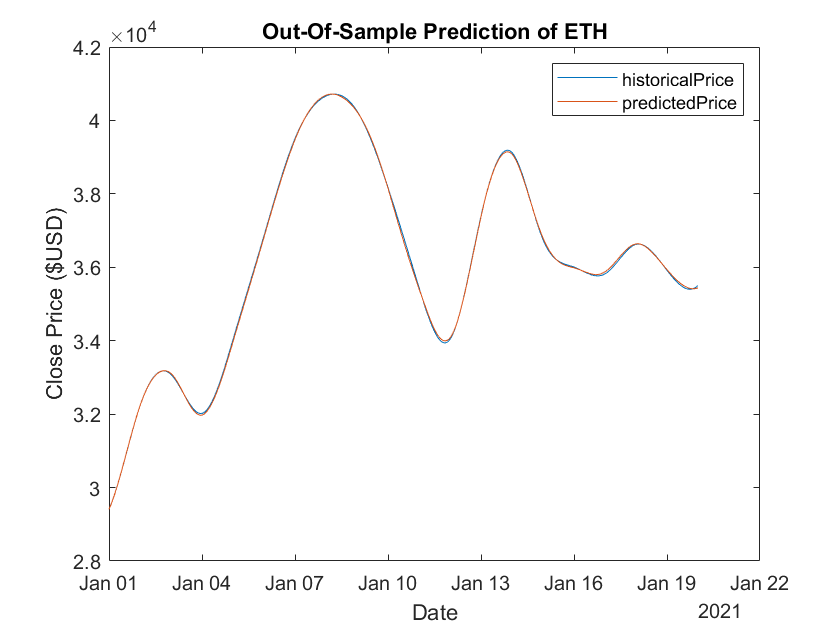

visualizeResults(resultsTable)

resultsTable(end-5:end,:)